clc;
close all;

Reading and displaying images

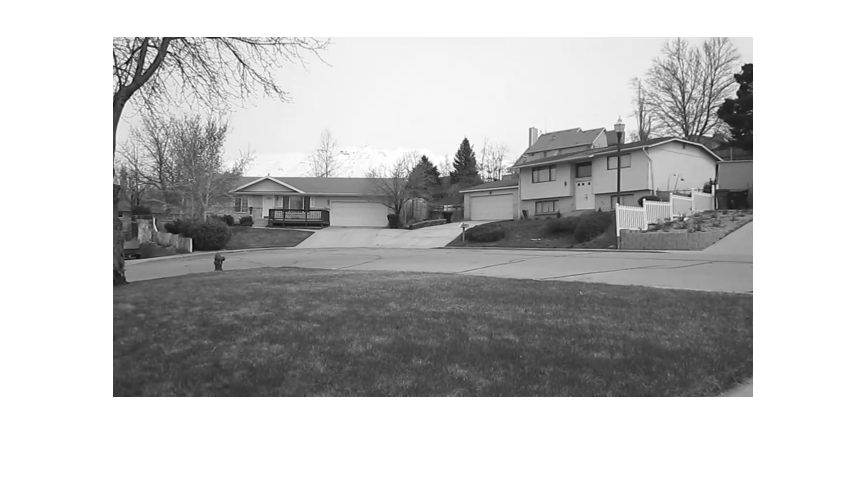

image1=imread("img1.png");
imshow(image1);

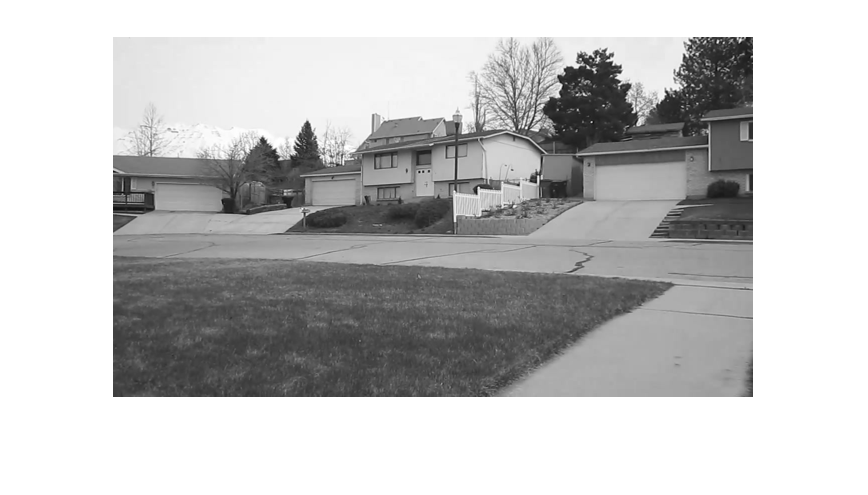

image2=imread("img2.png");
imshow(image2);

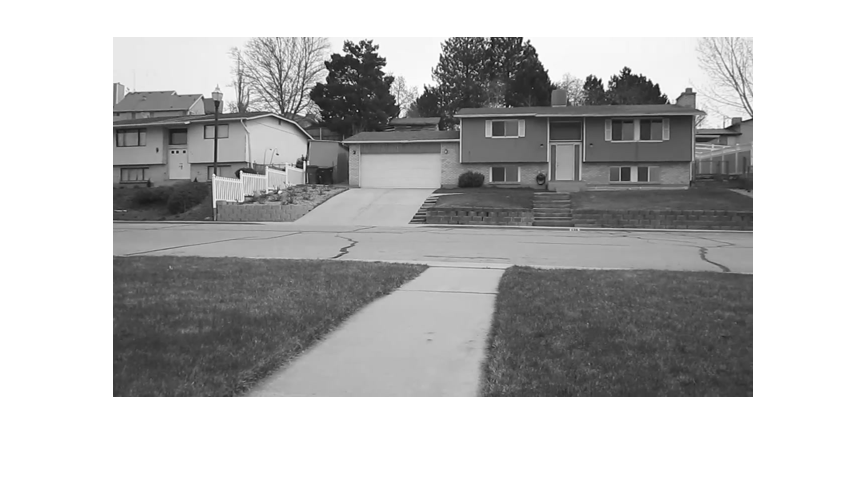

image3=imread("img3.png");
imshow(image3)

Setting the RANSAC parameters

e=10; %epsilon
max_iterations = 10^4; %maximum number of iterations
min_consensus=0.8; %setting the consensus as 80%
R=4; %cardinality of inital point sets considered for computing homography

Finding the corresponding points between images 1 and 2 using sift_corresp.m file provided to us.

[corresp1,corresp2]=sift_corresp("img1.png","img2.png");

Finding keypoints... 
1138 keypoints found. 
Finding keypoints... 
923 keypoints found. 


Calculating the Homography matrix between image2 and image1 as H21 by calling the RANSAC function

H21=ransac(corresp2,corresp1,min_consensus,e,max_iterations,R);

Finding the corresponding points between images 2 and 3 using sift_corresp.m file provided to us.

[corresp2,corresp3]=sift_corresp("img2.png","img3.png");

Finding keypoints... 
923 keypoints found. 
Finding keypoints... 
1114 keypoints found. 


Calculating the Homography matrix between image2 and image3 as H21 by calling the RANSAC function

H23=ransac(corresp2,corresp3,min_consensus,e,max_iterations,R);

Verifying whether  the size of images are same or not and then zero padding the images so that it will be useful while doing target to source mapping using bilinear interpolation.

[x1,y1]=size(image1)

x1 = 360

y1 = 640

[x2,y2]=size(image2)

x2 = 360

y2 = 640

[x3,y3]=size(image3)

x3 = 360

y3 = 640

temp_image = zeros(x1+2, y1+2);
temp_image(2:x1+1, 2:y1+1) = image1;
img1 = temp_image;
temp_image = zeros(x2+2, y2+2);
temp_image(2:x2+1, 2:y2+1) = image2;
img2 = temp_image;
temp_image = zeros(x3+2, y3+2);
temp_image(2:x3+1, 2:y3+1) = image3;
img3 = temp_image;
clear temp_image;

Creating empty canvas and the size is choosen in such a way that the stitched image can fit in.

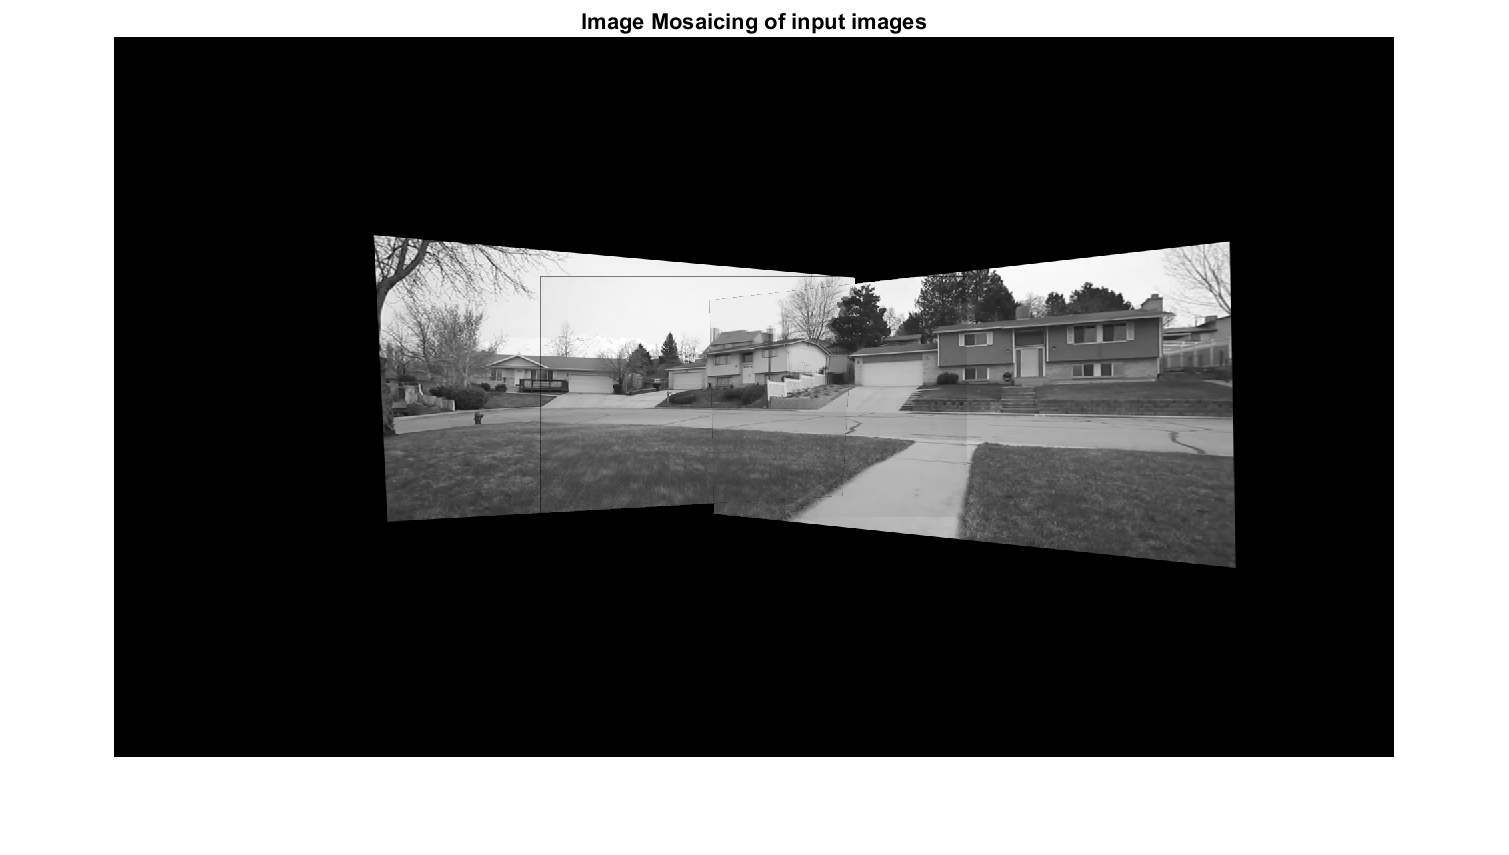

%canvas
rows_c = x1+x2+x3; %row dimensions of canvas 
cols_c = y1+y2+y3; %column dimensions of canvas
canvas = zeros(rows_c, cols_c);

%as we are stitching images and image 2 will be the common image for both 1
%and 3, we expect the image 2 to be in the center of the canvas, i am
%setting these offset values.
offset_row=ceil(rows_c/3); 
offset_col=ceil(cols_c/3);

for x_canvas = 1:rows_c
    for y_canvas = 1:cols_c
        xt = x_canvas - offset_row; 
        yt = y_canvas - offset_col;
        
        target_image = [xt; yt;1]; %homogeneous co-ordinates form
        %calculating corresponding points using the Hij matrices obtained 
        [xs1, ys1] = calculate_corresp_pts(H21, target_image); 
        [xs3, ys3] = calculate_corresp_pts(H23, target_image);
        
        %performing target to source mapping using bilinear interpolation
        [Intensity_val1, incanvas1] = bilinearInterpolation(img1, xs1, ys1);
        [Intensity_val3, incanvas3] = bilinearInterpolation(img3, xs3, ys3);
        [Intensity_val2, incanvas2] = bilinearInterpolation(img2, xt, yt);
        
        Intensity = 0; %intially setting the intensity value to 0
        if incanvas1==1 && incanvas2==0 && incanvas3==0
            Intensity = Intensity+Intensity_val1;
        
        elseif incanvas1==0 && incanvas2==1 && incanvas3==0
            Intensity = Intensity+val2;
        
        elseif incanvas1==0 && incanvas2==0 && incanvas3==1
            Intensity = Intensity+Intensity_val3;
            
        elseif incanvas1==1 && incanvas2==1 && incanvas3==0
            Intensity= 0.5*Intensity_val1 + 0.5*Intensity_val2;
        
        elseif incanvas1==1 && incanvas2==0 && incanvas3==1
            Intensity= 0.5*Intensity_val1 + 0.5*Intensity_val3;
        
        elseif incanvas1==0 && incanvas2==1 && incanvas3==1
            Intensity= 0.5*Intensity_val2 + 0.5*Intensity_val3;
            
        elseif incanvas1==1 && incanvas2==1 && incanvas3==1
            Intensity= 0.333*Intensity_val1 + 0.333*Intensity_val2+0.333*Intensity_val3;
        
        end
        
        canvas(x_canvas, y_canvas) = Intensity;
    end
end
%Intensity values of canvas will be float values so if we perform
%imshow(canvas) and by default matlab assumes the pixels with values
%greater than 1 as saturated pixels so to avoid this we are using 'uint8'
canvas = uint8(canvas);
imshow(canvas);
title("Image Mosaicing of input images");

Cropping the stitched image 

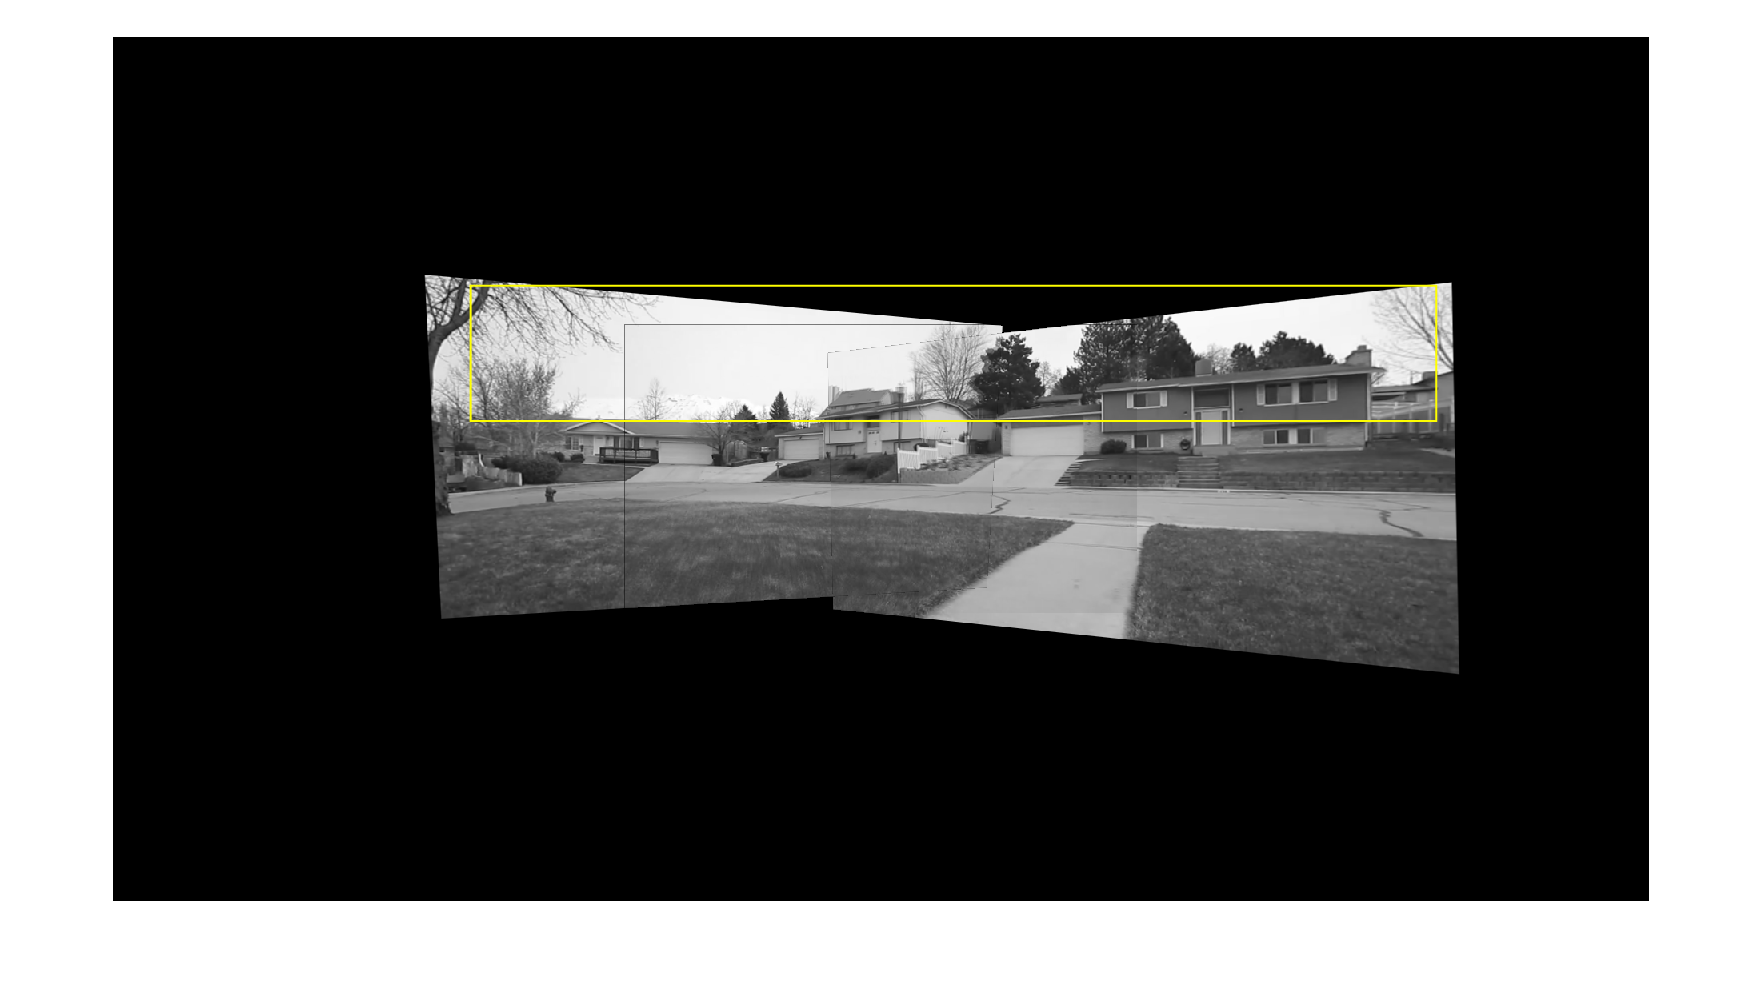

S = regionprops(canvas,'BoundingBox','Area');
[MaxArea,MaxIndex] = max(cat(S.Area));
imshow(canvas,'InitialMagnification',80)
%// Highlight the required object
hold on
rectangle('Position',S(MaxIndex).BoundingBox,'LineWidth',1,'EdgeColor','y')

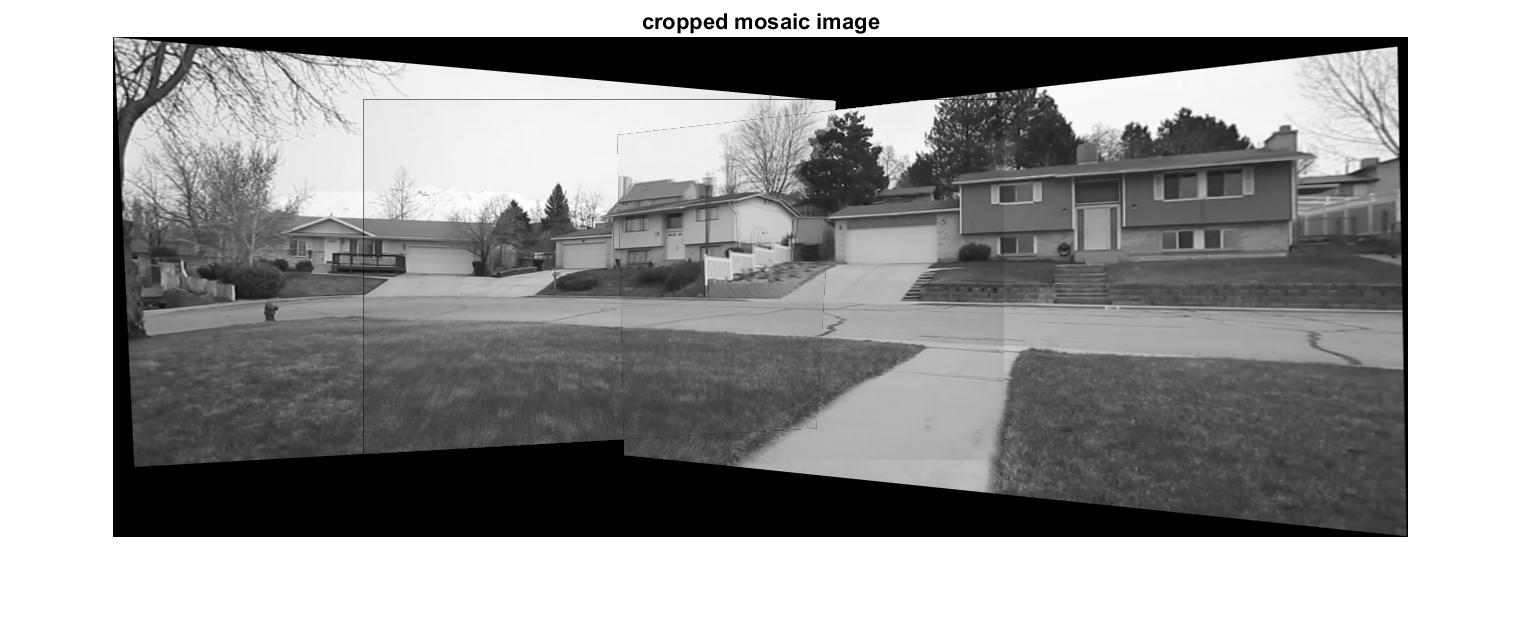

Length = S(MaxIndex).BoundingBox(3);
Height = S(MaxIndex).BoundingBox(4);
% Cropping the image
% Get all rows and columns where the image is nonzero
[nonZeroRows,nonZeroColumns] = find(canvas);
% Get the cropping parameters
topRow = min(nonZeroRows(:));
bottomRow = max(nonZeroRows(:));
leftColumn = min(nonZeroColumns(:));
rightColumn = max(nonZeroColumns(:));
% Extract a cropped image from the original.
croppedImage = canvas(topRow:bottomRow, leftColumn:rightColumn);
figure
imshow(croppedImage, []);
title("cropped mosaic image")